# EE 354 HW 6 Computer Exercise

### 3B.1.a & 3B.1.b

Assume A1 = A2 = 5, f1 = 100 Hz, f2 = 105 Hz, φ`1` = φ`2` = 0, T = 127 ms (millisecond), fs = 1000 Hz. Determine and plot the signal. Determine the Fourier transform of the signal using FFT and plot the magnitude of the Fourier transform for frequencies between 80 Hz and 120 Hz.

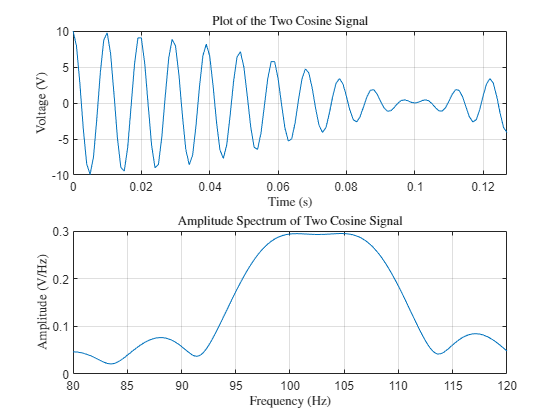

% Generate sampled signal
A1 = 5; A2 = 5;
f1 = 100; f2 = 105;
phi1 = 0; phi2 = 0;
T = 127e-3; 
fs = 1000;
ts = 1/fs;
[signal, time] = twoCosine(A1, f1, phi1, A2, f2, phi2, T, fs);

% Plot sampled signal
figure(1)
subplot(2,1,1);
plot(time, signal);
grid on; xlim([time(1), time(end)]); % ylim([-1.5, 1.5]);
title('Plot of the Two Cosine Signal','Interpreter',"latex");
xlabel('Time (s)','Interpreter',"latex"); ylabel('Voltage (V)','Interpreter',"latex");

% Generate frequency axis
N = 2^15;
df = fs/N;
f = -(fs/2 - df) : df : fs/2;

% Plot Fourier transform of sampled signal
S = ts*fftshift(fft(signal, N));
subplot(2,1,2);
plot(f, abs(S));
grid on; xlim([80, 120]); % ylim([]);
title('Amplitude Spectrum of Two Cosine Signal','Interpreter',"latex");
xlabel('Frequency (Hz)','Interpreter',"latex"); ylabel('Amplitude (V/Hz)','Interpreter',"latex");

### 3B.1.c

Now assume T = 1023 ms and all other parameters same as in (3B.1.b). Determine and plot the signal. Determine the Fourier transform of the signal using FFT and plot the magnitude of the Fourier transform for frequencies between 80 Hz and 120 Hz.

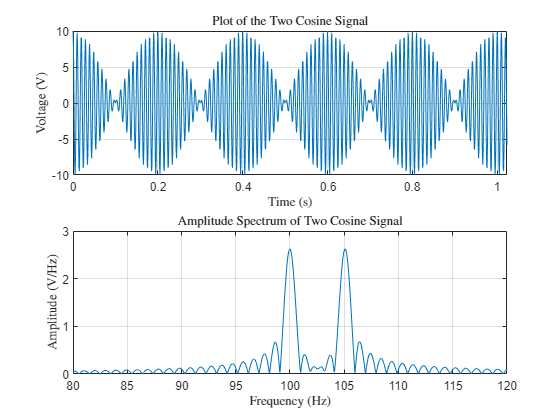

T = 1023e-3;
[signal, time] = twoCosine(A1, f1, phi1, A2, f2, phi2, T, fs);

% Plot sampled signal
figure(2)
subplot(2,1,1);
plot(time, signal);
grid on; xlim([time(1), time(end)]); % ylim([-1.5, 1.5]);
title('Plot of the Two Cosine Signal','Interpreter',"latex");
xlabel('Time (s)','Interpreter',"latex"); ylabel('Voltage (V)','Interpreter',"latex");

% Plot Fourier transform of sampled signal
S = ts*fftshift(fft(signal, N));
subplot(2,1,2);
plot(f, abs(S));
grid on; xlim([80, 120]); % ylim([]);
title('Amplitude Spectrum of Two Cosine Signal','Interpreter',"latex");
xlabel('Frequency (Hz)','Interpreter',"latex"); ylabel('Amplitude (V/Hz)','Interpreter',"latex");

### 3B.1.d

Discuss you results in a few lines.

### 3B.2.a

Assume A1 = 5, A2 = 0, f1 = 150 Hz, Hz, φ`1` = 0, T = 1022 ms, fs = 500 Hz. Determine and plot the signal. Determine the Fourier transform of the signal using FFT and plot the magnitude of the Fourier transform for frequencies between 0 Hz and 250 Hz.

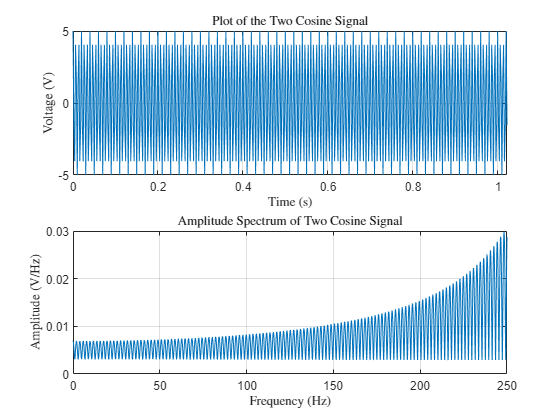

% Generate sampled signal
A1 = 5; A2 = 0;
f1 = 150;
phi1 = 0;
T = 1022e-3; 
fs = 500;
ts = 1/fs;
[signal, time] = twoCosine(A1, f1, phi1, A2, f2, phi2, T, fs);

% Plot sampled signal
figure(3)
subplot(2,1,1);
plot(time, signal);
grid on; xlim([time(1), time(end)]); % ylim([-1.5, 1.5]);
title('Plot of the Two Cosine Signal','Interpreter',"latex");
xlabel('Time (s)','Interpreter',"latex"); ylabel('Voltage (V)','Interpreter',"latex");

% Plot Fourier transform of sampled signal
S = ts*fftshift(fft(signal, N));
subplot(2,1,2);
plot(f, abs(S));
grid on; xlim([0, 250]); % ylim([]);
title('Amplitude Spectrum of Two Cosine Signal','Interpreter',"latex");
xlabel('Frequency (Hz)','Interpreter',"latex"); ylabel('Amplitude (V/Hz)','Interpreter',"latex");

### 3B.2.b

Assume A1 = 5, A2 = 0, f1 = 150 Hz, Hz, φ`1` = 0, T = 1275 ms, fs = 200 Hz. Determine and plot the signal. Determine the Fourier transform of the signal using FFT and plot the magnitude of the Fourier transform for frequencies between 0 Hz and 100 Hz.

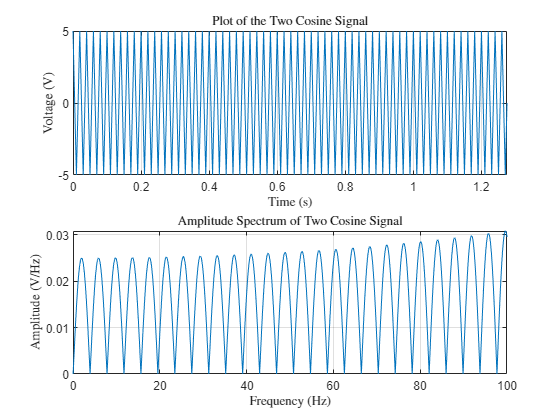

% Generate sampled signal
A1 = 5; A2 = 0;
f1 = 150;
phi1 = 0;
T = 1275e-3; 
fs = 200;
ts = 1/fs;
[signal, time] = twoCosine(A1, f1, phi1, A2, f2, phi2, T, fs);

% Plot sampled signal
figure(4)
subplot(2,1,1);
plot(time, signal);
grid on; xlim([time(1), time(end)]); % ylim([-1.5, 1.5]);
title('Plot of the Two Cosine Signal','Interpreter',"latex");
xlabel('Time (s)','Interpreter',"latex"); ylabel('Voltage (V)','Interpreter',"latex");

% Plot Fourier transform of sampled signal
S = ts*fftshift(fft(signal, N));
subplot(2,1,2);
plot(f, abs(S));
grid on; xlim([0, 100]); % ylim([]);
title('Amplitude Spectrum of Two Cosine Signal','Interpreter',"latex");
xlabel('Frequency (Hz)','Interpreter',"latex"); ylabel('Amplitude (V/Hz)','Interpreter',"latex");

### 3B.2.c

Discuss you results in a few lines. What is the resolution of spectrum found in (3B.2.a)? What is it of that found in (3B.2.b)?